## 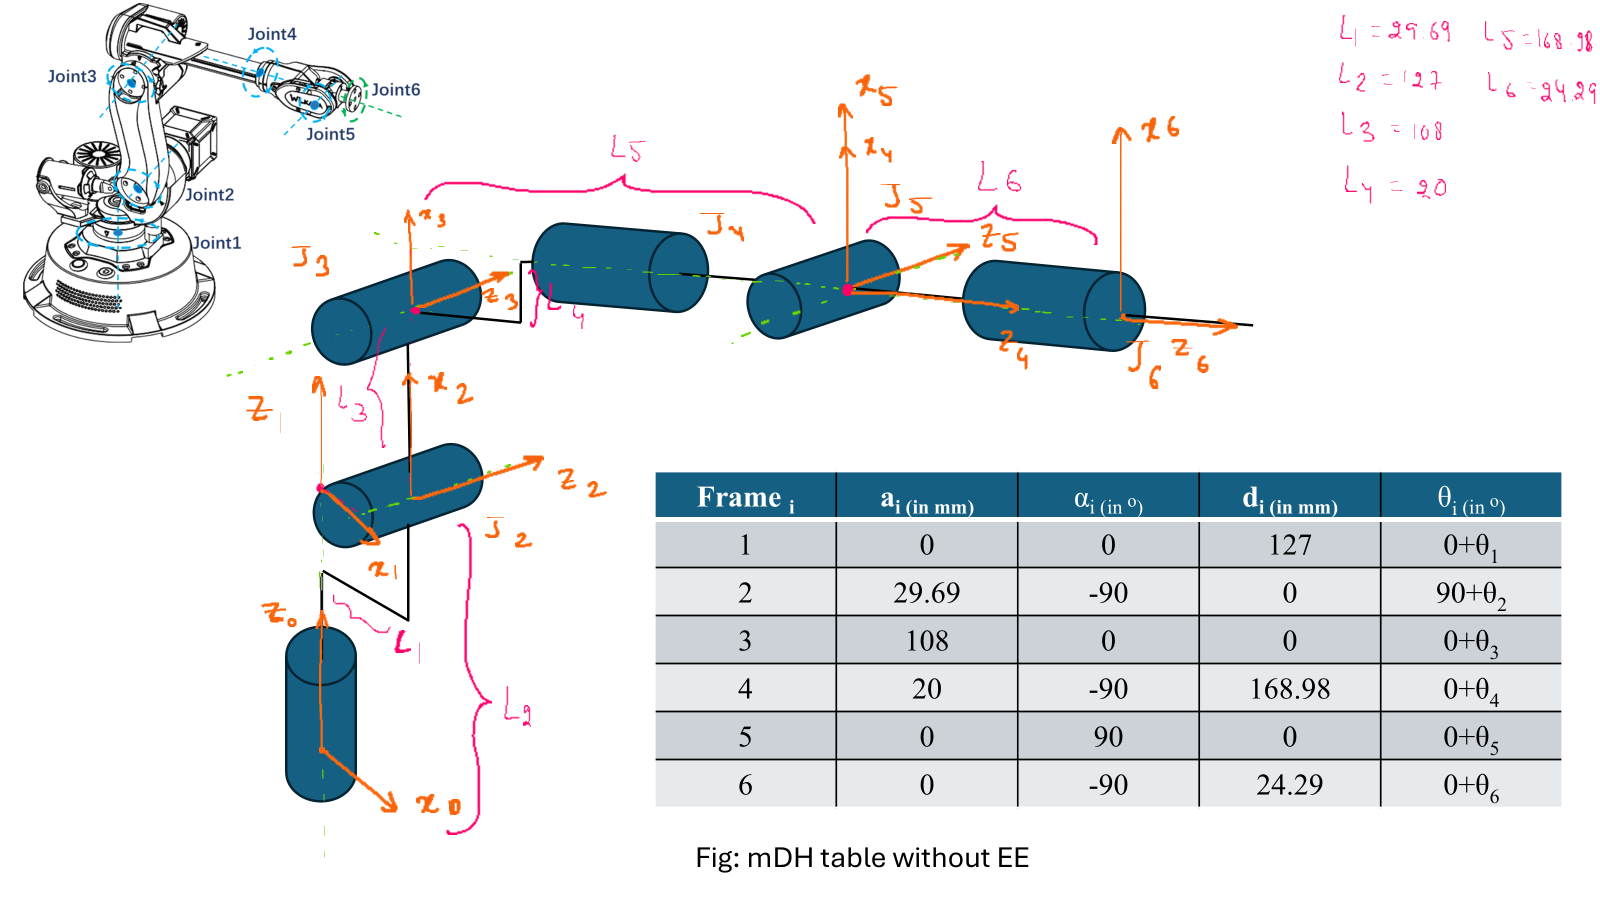

## DEFINE THE RIGID BODY TREE

clear;
robot = rigidBodyTree('DataFormat', 'column');

base = robot.Base;

arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");
arm4 = rigidBody("arm4");
arm5 = rigidBody("arm5");
arm6 = rigidBody("arm6");

%Create Ende-Effector Design
EE = zeros(16,3); %16x3 mesh
EE(1,:) = [0.01255/2, 0.02/2,  0.01];
EE(2,:) = [0.01255/2, 0.0228/2,  0];
EE(3,:) = [ 0.01255/2, 0.02/2,  -0.0144];
EE(4,:) = [ 0.01255/2, 0.05/2,  0];
EE(5,:) = [ 0.01255/2, -0.05/2,  0];
EE(6,:) = [ 0.01255/2, -0.02/2,  -0.0144];
EE(7,:) = [0.01255/2, -0.0228/2,  0];
EE(8,:) = [0.01255/2, -0.02/2,  0.01];
EE(9,:) = [-0.01255/2, 0.02/2,  0.01];
EE(10,:) = [-0.01255/2, 0.0228/2,  0];
EE(11,:) = [-0.01255/2, 0.02/2,  -0.0144];
EE(12,:) = [-0.01255/2, 0.05/2,  0];
EE(13,:) = [-0.01255/2, -0.05/2,  0];
EE(14,:) = [-0.01255/2, -0.02/2,  -0.0144];
EE(15,:) = [-0.01255/2, -0.0228/2,  0];
EE(16,:) = [-0.01255/2, -0.02/2,  0.01];

% Create and add collision boxes to each part of the robot
collisionBox1 = collisionCylinder(0.08,0.1); % (radius, height)Base
collisionBox2 = collisionCylinder(0.04,0.127); % (radius, height)arm1
collisionBox3 = collisionBox(0.108,0.02969,0.02969); % (width, depth, height)(x,y,z)
collisionBox4 = collisionCylinder(0.02,0.04); % (width, depth, height)(x,y,z)
collisionBox5 = collisionCylinder(0.02,0.16898); % (width, depth, height)(x,y,z)
collisionBox6 = collisionCylinder(0.02,0.04); % (width, depth, height)(x,y,z)
collisionBox7 = collisionCylinder(0.01,0.02429); % (width, depth, height)(x,y,z)
collisionBox8 = collisionMesh(EE);

 
% Set transformations for the collision boxes
tform1 = trvec2tform([0, 0, 0.05]);
tform2 = trvec2tform([0, 0, -0.127/2]);
tform3 = trvec2tform([0.108/2, 0, 0]);
tform4 = trvec2tform([0,0, 0]);
tform5 = trvec2tform([0,0, -0.16898/2]);
tform6 = trvec2tform([0,0, 0]);
tform7 = trvec2tform([0,0, 0]);
tform8 = trvec2tform([0, 0, 0.02429]);

% Add collision boxes to each rigid body (for example, arm1, arm2, etc.)
addCollision(base, collisionBox1, tform1);
addCollision(arm1, collisionBox2, tform2);
addCollision(arm2, collisionBox3, tform3);
addCollision(arm3, collisionBox4, tform4);
addCollision(arm4, collisionBox5, tform5);
addCollision(arm5, collisionBox6, tform6);
addCollision(arm6, collisionBox7, tform7);
addCollision(arm6, collisionBox8, tform8);

% set joints as revolute joints

jnt1 = rigidBodyJoint("jnt1", "revolute");
jnt2 = rigidBodyJoint("jnt2", "revolute");
jnt3 = rigidBodyJoint("jnt3", "revolute");
jnt4 = rigidBodyJoint("jnt4", "revolute");
jnt5 = rigidBodyJoint("jnt5", "revolute");
jnt6= rigidBodyJoint("jnt6", "revolute");

%          a          alpha        d          theta  
dhparams = [0         0           0.127      0;         % Frame 1
            0.02969   -pi/2       0          0;         % Frame 2
            0.108     0           0          0;         % Frame 3
            0.02      -pi/2       0.16898    0;         % Frame 4
            0         pi/2        0          0;         % Frame 5
            0         -pi/2       0.02429    0];        % Frame 6


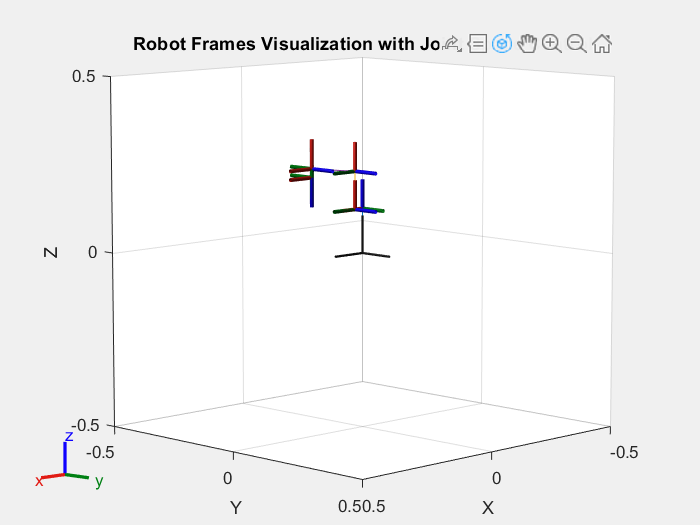

bodies = {base,arm1, arm2, arm3, arm4, arm5, arm6}; % endeffector};
joints = {[], jnt1, jnt2, jnt3, jnt4, jnt5, jnt6};
homeconfig = [0, -pi/2, 0, 0,pi/2,0]';

for i = 2:length(bodies)
    setFixedTransform(joints{i}, dhparams(i-1,:), "mdh");
    bodies{i}.Joint = joints{i};
    addBody(robot, bodies{i}, bodies{i-1}.Name)
    drawnow;
end

figure;
show(robot,homeconfig(),"Collisions","off");
title('Robot Frames Visualization with Joint Space Control');

% Set the initial configuration and final joint angles for six joints
finalconfig  = [0, -pi/2, 0, 0,pi/2,0]';  % Setting final angles for six joints

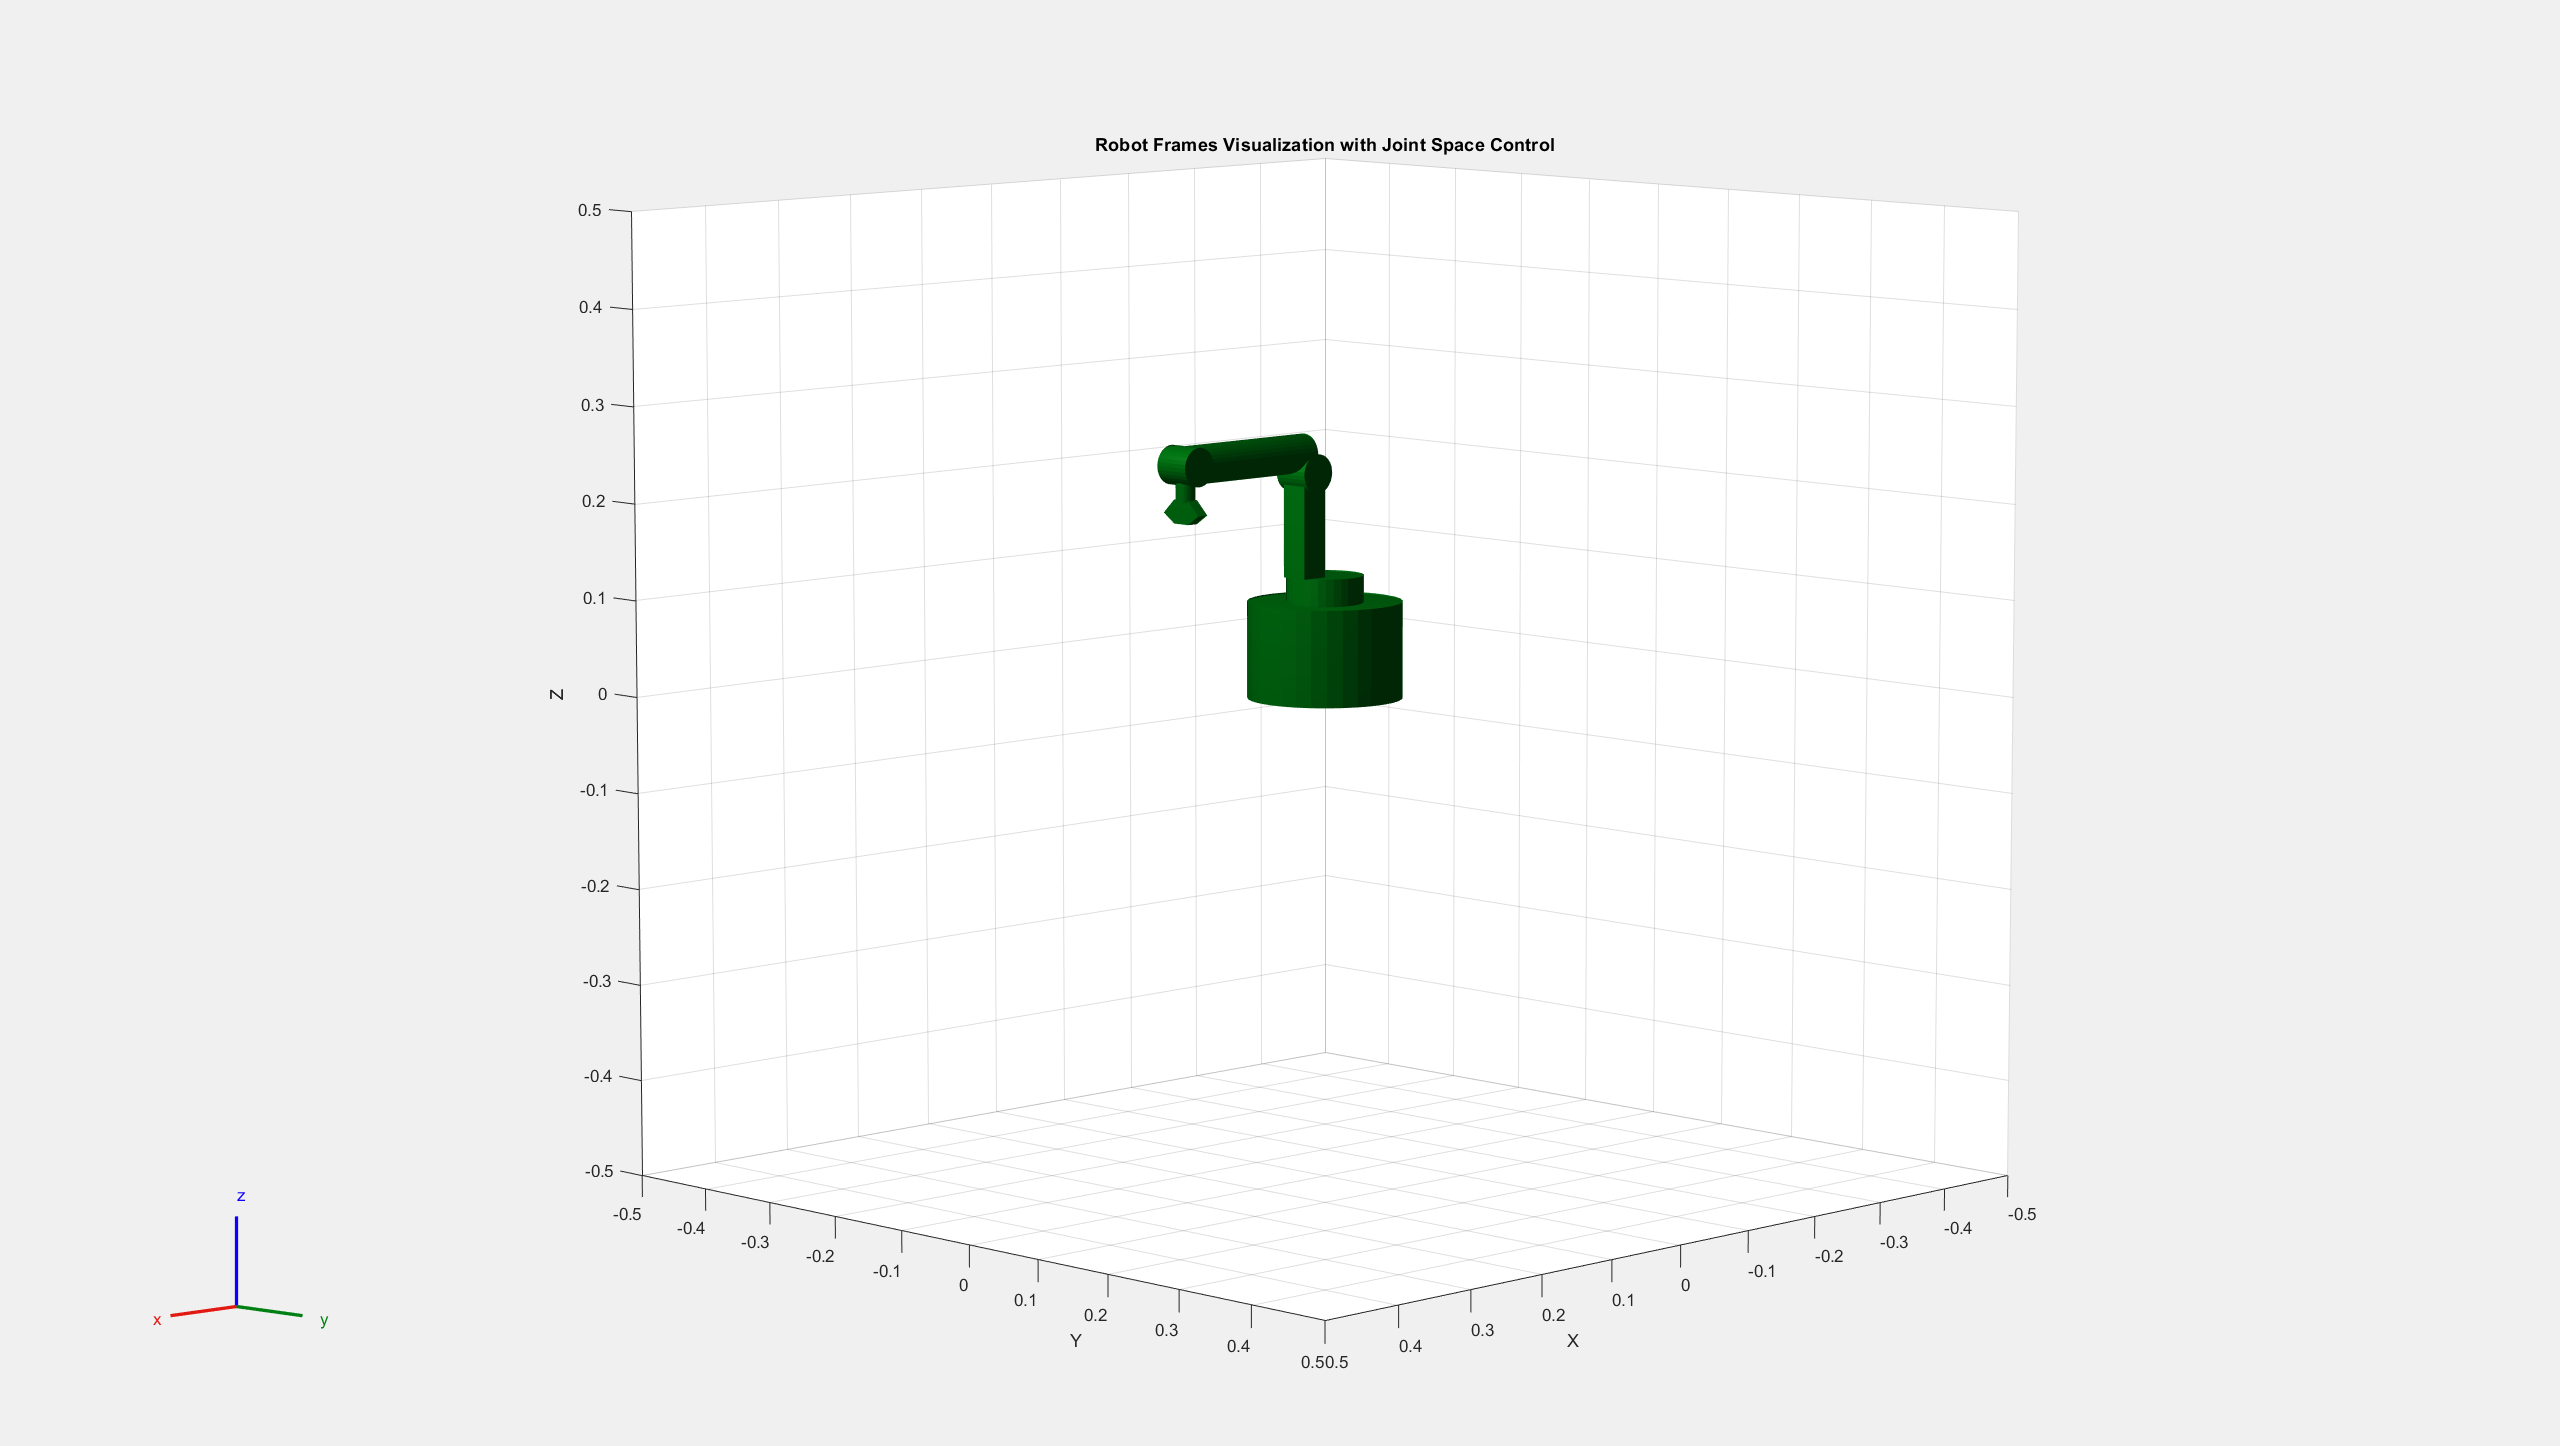

% Set initial and final configurations
Initial = homeconfig;
Final = finalconfig;
Step = 90;
framesPerSecond = 150;

% Calculate incremental step for each joint angle
Qd = (Final - Initial) / Step;

% Preallocate F to store frames
F(Step) = struct('cdata', [], 'colormap', []);

% Generate frames by interpolating between Initial and Final configurations
for i = 1:Step
    q = Initial + Qd * i;
    % Show robot at current configuration q
    show(robot, q, 'PreservePlot', false,'Collisions','on','Frames','off'); % Update robot configuration
    title('Robot Frames Visualization with Joint Space Control');
    drawnow;

    % Capture the current figure as a frame
    F(i) = getframe(gcf);
end


% Set up video writer with specified frame rate
writerObj = VideoWriter('fkVideo.avi');
writerObj.FrameRate = framesPerSecond;

% Open the video writer
open(writerObj);

% Write each frame to the video file
for i = 1:Step
    writeVideo(writerObj, F(i));
end

Error using VideoWriter/writeVideo (line 368)
Frame must be 700 by 525


% Close the video writer
close(writerObj);